# Taller IV

### 17/04/2022 2022-01S

#### Métodos Númericos

#### *Resumen sobre la semana 3 y 4*

*Notas para el uso de MATLAB:*

- Frente a las operaciones de númericas tenemos 2 definiciones distintas y es importante separarlas, las operaciones $+-*\;/$, son directas matriciales, en cambio las prefijadas con ${\prime \ldotp }^{\prime }$, son *element-wise*, o sea se realizan en cada uno de los elementos del argumento entregado a la función. Importante en la notación con @

- No olvidar el criterio de parada de ErrorRelativo, ya que en general este error converge primero que el Error Absoluto, y esto detiene el metodo antes de un delta deseado, si el método se encuentra programado de esta manera es importante no modificar este criterio, y de igual manera esto se verá reflejado en el criterio $\textrm{Err}$ que nos retorna el método.

- Importante, pero esto es más un recordatorio. Matlab es además de un software un lenguaje, así podemos tareas repetitivas volverlas métodos iterativos, eso es lo que se les propone con el método **Jac_GS**, invitarlos a que exploren la posibilidad y realicen métodos que les haga la vida más fácil.

- Si se necesita conocer información sobre un método o sobre alguna rutina, es comando `help ``rutina` resulta bastante útil.

*Notas frente al uso de los métodos:*

#### *        Métodos de sistemas de ecuaciones*

`    X = jacobi(A, B, P, delta, max1), `Método de Jacobi.

            - A es una matriz no singular  N x N

            - B es una matriz  N x 1

            - P es una matriz  N x 1; los supuestos iniciales

            - delta es la tolerancia para  P

            - max1 es el numero maximo de iteraciones

            - X es una matriz  N x 1: la aproximacion de jacobi a

                la solucion de  AX = B

`    X = gseid(A, B, P, delta, max1), `Método de Gauss - Seidel.

            - A es una matriz no singular  N x N

            - B es una matriz  N x 1

            - P es una matriz  N x 1; el supuesto inicial

            - delta es la tolerancia para  P

            - max1 es el numero maximo de iteraciones

            - X es una matriz  N x 1: la aproximacion de gauss-seidel a

                la solucion de  AX = B

`    Y = sor(A, B, P, w, delta, max1), `Método de SOR

            - A es una matriz no singular  N x N

            - B es una matriz  N x 1

            - P es una matriz  N x 1; el supuesto inicial

            - w parametro de sobrerelajacion (0<w<2)

            - delta es la tolerancia para  P

            - max1 es el numero maximo de iteraciones

             - Y es una matriz  N x 1: la aproximacion de SOR a

                la solucion de  AX = B

`    P = newdim (F, JF, P, delta, epsilon, max1), `Método de Newton

            - F funcion del sistema creada con @

            - JF matriz jacobiana, funcion creada con @

            - P es la aproximacion inicial a la solucion

            - delta es la tolerancia para  P

            - epsilon es la tolerancia para  F(P)

            - max1 es el numero maximo de iteraciones

            - P es la aproximacion a la solucion

            - iter es el numero de iteraciones realizadas

            - err es el error estimado para  P

Recordar documentarse en cada una de las rutinas disponibles del curso y de MATLAB para afrontar distintas situaciones, MATLAB es su aliado.

#### Sistemas de ecuaciones no lineales

Para el taller de esta semana se solucionan los ejercicios $8$ del taller 4, se propone el uso de Newtondim y las propias herramientas de Matlab

**8) **Utilice el método de Newton para aproximar las raices de los sistemas:

$\begin{array}{l}
x^3 +3y^2 =21\\
x^2 +2y+2=0
\end{array}$  y  $\begin{array}{l}
4-x^2 -y^2 =0\\
1-e^x -y=0
\end{array}$

Como primera aproximación use `ones(2, 1), `en cada caso.


$$F\left(X\right)=0\;,F\left(x,y\right)=0\to F\left(X\right)=0$$


clear
syms F(x, y)

F(x, y) = [x^3 + 3*y^2 - 21; x^2 + 2*y + 2]'

$$F(x, y) = \left(\begin{array}{cc} 3\,y^{2}+{\left(\bar{x}\right)}^{3}-21 & {\left(\bar{x}\right)}^{2}+2\,y+2 \end{array}\right)$$

JF(x, y) = jacobian(F)

$$JF(x, y) = \left(\begin{array}{cc} 3\,{\left(\bar{x}\right)}^{2} & 6\,y\\ 2\,\bar{x} & 2 \end{array}\right)$$

F = matlabFunction(F)

F = function_handle with value:
    @(x,y)[conj(x).^3+y.^2.*3.0-2.1e+1,y.*2.0+conj(x).^2+2.0]


JF = matlabFunction(JF)

JF = function_handle with value:
    @(x,y)reshape([conj(x).^2.*3.0,conj(x).*2.0,y.*6.0,2.0],[2,2])


help newdim

  Entrada  - F funcion del sistema creada con @
             JF matriz jacobiana, funcion creada con @
           - P es la aproximacion inicial a la soluion
           - delta es la tolerancia para  P
           - epsilon es la tolerancia para  F(P)
           - max1 es el numero maximo de iteraciones
  Salida   - P es la aproximacion a la solucion
           - iter es el numero de iteraciones realizadas
           - err es el error estimado para  P



F = @(X) F(X(1), X(2)); % X = [x, y]
JF = @(X) JF(X(1), X(2));

X0 = ones(2, 1)'

X0 =      1     1


X = newdim(F, JF, X0, 1e-15, 1e-15, 100)

X =     1.6430   -2.3498



$$\begin{array}{l}
4-x^2 -y^2 =0\\
1-e^x -y=0
\end{array}$$


clear
syms F(x, y)

F(x, y) = [4 - x^2 - y^2; 1 - exp(x) - y]'

$$F(x, y) = \left(\begin{array}{cc} -x^{2}-y^{2}+4 & 1-{\mathrm{e}}^{x}-y \end{array}\right)$$

x0 = ones(2, 1)'

x0 =      1     1


JF(x, y) = jacobian(F)

$$JF(x, y) = \left(\begin{array}{cc} -2\,x & -2\,y\\ -{\mathrm{e}}^{x} & -1 \end{array}\right)$$

F = matlabFunction(F);
JF = matlabFunction(JF);
F = @(X) F(X(1), X(2));
JF = @(X) JF(X(1), X(2));

X = newdim(F, JF, x0, 1e-15, 1e-15, 100)

X =    -1.8163    0.8374


#### Interpolación

Para el taller de esta semana se solucionan los ejercicios $1,3$ del taller 6, se propone el uso de Newton y Lagrage, y las propias herramientas de Matlab

**1) **Se tienen las cesantias en los distintos fondos a febrero 16 de 2021:

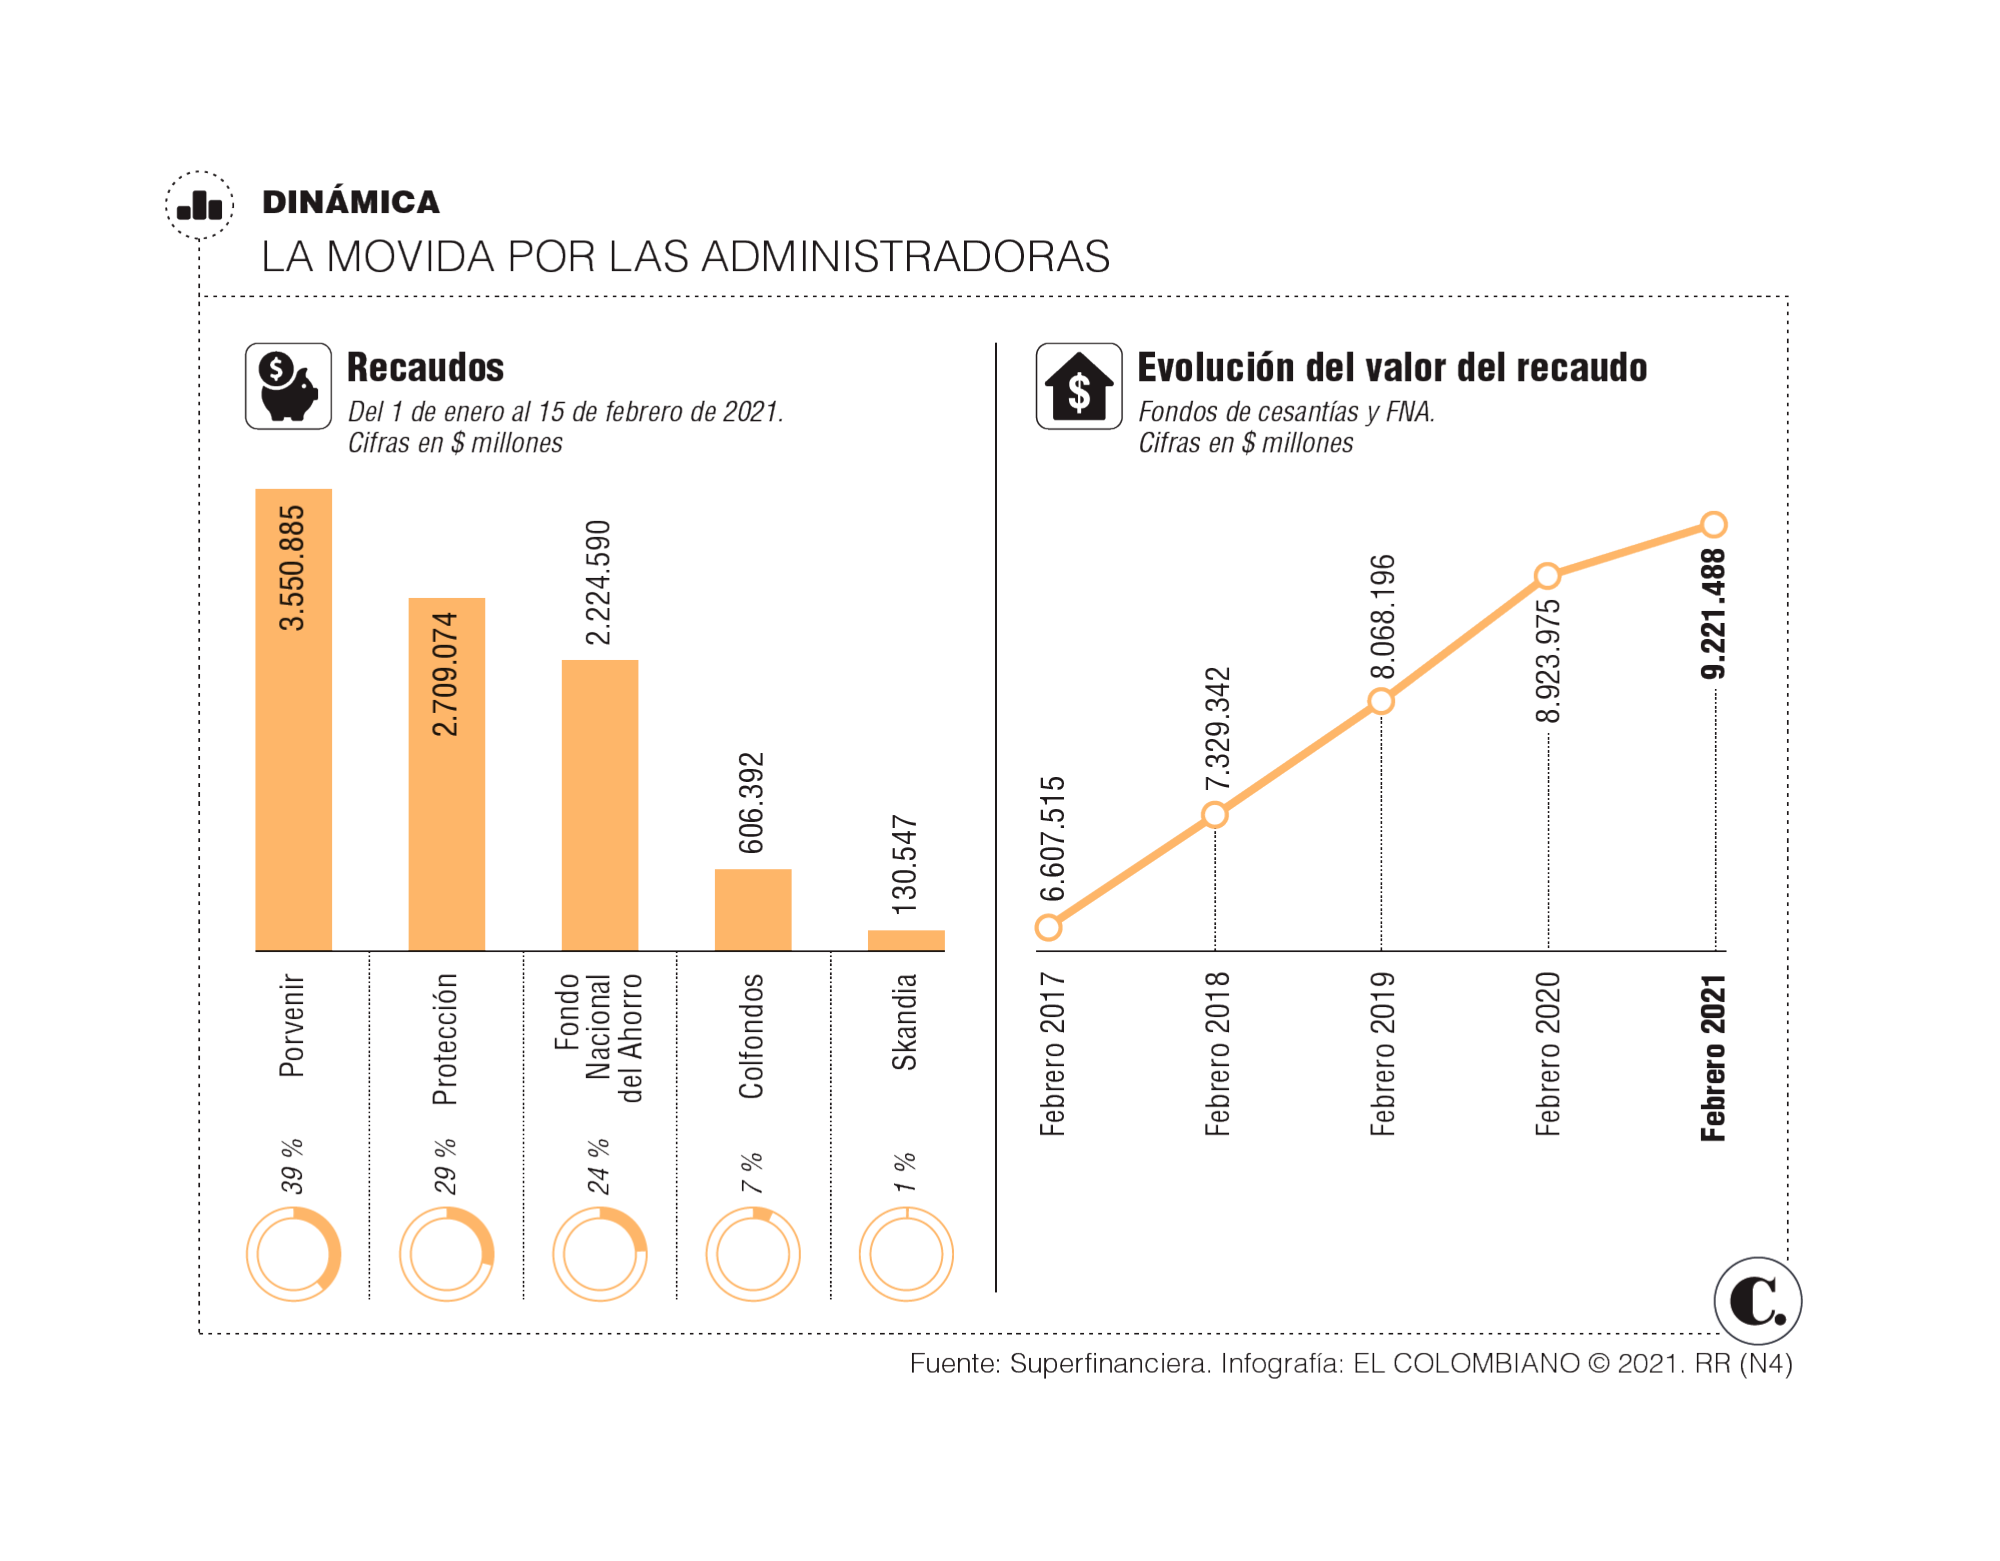

help newpoly

  Entrada   - X es un vector que contiene la lista de abscisas
            - Y es un vector que contiene la lista de ordenadas
  Saldia    - C es un vector que contiene los coeficientes del
              polinomio interpolante de Newton
            - D es la tabla de diferencias divididas



help lagran

  Entrada  - X es un vector que contiene una lista de las abscisas
           - Y es un vector que contiene una lista de las ordenadas
  Salida   - C es una matriz que contiene los coeficientes del
             polinomio interpolante de Lagrange
           - L es una matriz que contiene los coeficientes de los
             polinomios de Lagrange



**    a) **Encuentre el polinomio de grado 2 que interpola los datos correspondientes a los años 2017, 2018, 2019:

clear
syms x

t = 2017:2019 % Años

t =         2017        2018        2019


R = [6607.515 7329.342 8068.196] % Recaudos

R = 	1.0e+03 *

    6.6075    7.3293    8.0682


C = lagran(t, R)

C = 	1.0e+07 *

    0.0000   -0.0034    3.3203


poly2sym(C)

$$ans = \frac{18721384486143\,x^{2}}{2199023255552}-\frac{9027523442639\,x}{268435456}+\frac{17408056406573}{524288}$$

P = @(x) polyval(C, x) % Evaluo en valor

P = function_handle with value:
    @(x)polyval(C,x)


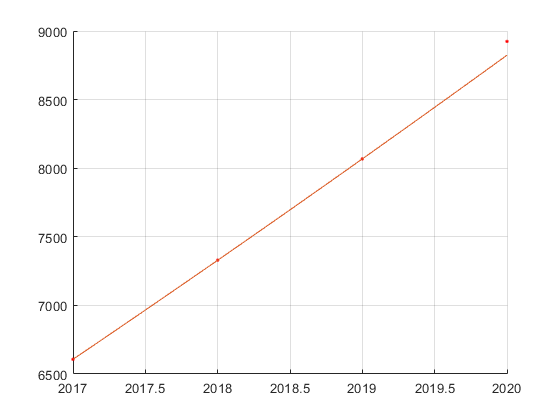

clf('reset')
hold on
plot(2017:2020, [6607.515 7329.342 8068.196 8923.975], '.r')
fplot(@(x) polyval(C, x), [2017, 2020])
grid on
hold off

**   b) **Evalue este en el año 2020, y comparelo con el verdadero:

P(2018) - 7329.342

ans = 6.9308e-07

polyval(C, 2020)

ans = 8.8241e+03

Absoluto = abs(8923.975 - P(2020))

Absoluto = 99.8980

Relativo = abs(8923.975 - P(2020)) / 8923.975 * 100

Relativo = 1.1194

**   c) **Encuentre el polinomio de grado 2 que interpola los datos correspondientes a los años 2018, 2019, 2020:

clear
syms x

t = 2018:2020; % Años
R = [7329.342 8068.196 8923.975]; % Recaudos
C = lagran(t, R);
poly2sym(C)

$$ans = \frac{4677\,x^{2}}{80}-\frac{31577976432755\,x}{134217728}+\frac{62052772385915}{262144}$$

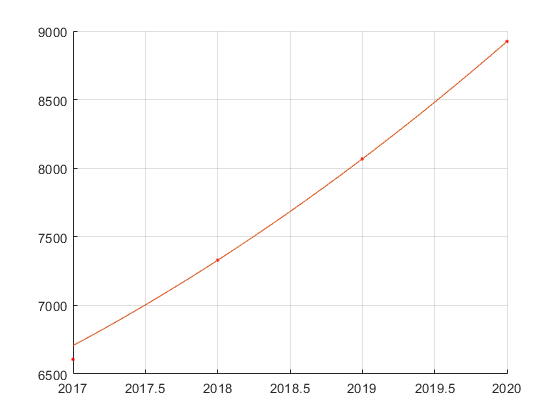

P = @(x) polyval(C, x); % Evaluo en valor
clf('reset')
hold on
plot(2017:2020, [6607.515 7329.342 8068.196 8923.975], '.r')
fplot(@(x) polyval(C, x), [2017, 2020])
grid on
hold off

P(2017)

ans = 6.7074e+03

help newpoly

  Entrada   - X es un vector que contiene la lista de abscisas
            - Y es un vector que contiene la lista de ordenadas
  Saldia    - C es un vector que contiene los coeficientes del
              polinomio interpolante de Newton
            - D es la tabla de diferencias divididas



help lagran

  Entrada  - X es un vector que contiene una lista de las abscisas
           - Y es un vector que contiene una lista de las ordenadas
  Salida   - C es una matriz que contiene los coeficientes del
             polinomio interpolante de Lagrange
           - L es una matriz que contiene los coeficientes de los
             polinomios de Lagrange



[coef, D] = newpoly(t, R)

coef = 	1.0e+08 *

    0.0000   -0.0024    2.3671


D = 	1.0e+03 *

    7.3293         0         0
    8.0682    0.7389         0
    8.9240    0.8558    0.0585


[coef, L] = lagran(t, R)

coef = 	1.0e+08 *

    0.0000   -0.0024    2.3671


L = 	1.0e+06 *

    0.0000   -0.0020    2.0392
   -0.0000    0.0040   -4.0764
    0.0000   -0.0020    2.0372



$$L=a_1 \frac{\left(x-x_1 \right)\;\ldotp \ldotp \ldotp \left(x-x_n \right)}{\left(x_i -x_1 \right)\;\ldotp \ldotp \ldotp \left(x_i -x_n \right)}+\ldotp \ldotp \ldotp +a_n \;\frac{\left(x-x_1 \right)\;\ldotp \ldotp \ldotp \left(x-x_n \right)}{\left(x_i -x_1 \right)\;\ldotp \ldotp \ldotp \left(x_i -x_n \right)}$$


**   d) **Encuentre el polinomio de grado 4 que interpola los cinco puntos de la gráfica:

clear
syms x

t = 2017:2020; % Años
R = [6607.515 7329.342 8068.196 8923.975]; % Recaudos
C = newpoly(t, R);
poly2sym(C) % Conocer el polinomio

$$ans = \frac{49949\,x^{3}}{3000}-\frac{3463068844145219\,x^{2}}{34359738368}+\frac{3412064033721085\,x}{16777216}-\frac{560303671519535}{4096}$$

D = polyder(C)

D = 	1.0e+08 *

    0.0000   -0.0020    2.0337


poly2sym(D)

$$ans = \frac{49949\,x^{2}}{1000}-\frac{3463068844145219\,x}{17179869184}+\frac{3412064033721085}{16777216}$$

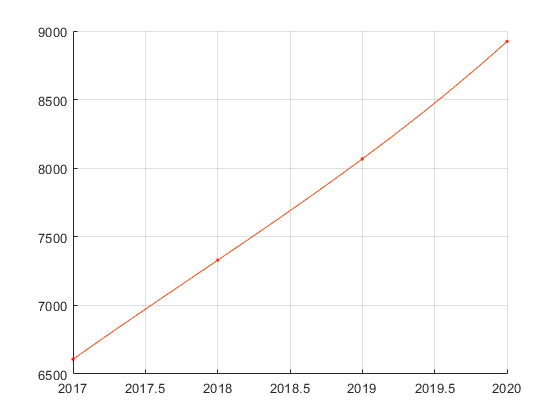

P = @(x) polyval(C, x); % Evaluo en valor
clf('reset')
hold on
plot(2017:2020, [6607.515 7329.342 8068.196 8923.975], '.r')
fplot(@(x) polyval(C, x), [2017, 2020])
grid on
hold off

P(t) - R 

ans = 	1.0e+-3 *

   -0.0311   -0.0505   -0.0771   -0.1007


**3) **En cada caso considere la tabla $\left\lbrack x_j ,f\left(x_j \right)\right\rbrack$. Para la tabla obtenga el polinomio interpolante de grado a lo más $n$ por el método de Lagrage y encuentre la cota para el error absoluto que resulta al interpolar el intervalo $\left\lbrack x_0 ,x_n \right\rbrack$:

    **a) **$f\left(x\right)=e^{2\;x} \;\cos \left(3\;x\right),$    $x_0 =0,x_1 =0\ldotp 3,x_2 =0\ldotp 6,n=2$

Recordemos que el error de cualquier polinomio interpolante a lo más $n$ con nodos selectos, es de:


$$E\left(x\right)=\frac{f^{\left(n+1\right)} \left(\xi \left(x\right)\right)}{\left(n+1\right)!}\;\prod_{i=0}^n \left(x-x_i \right)$$


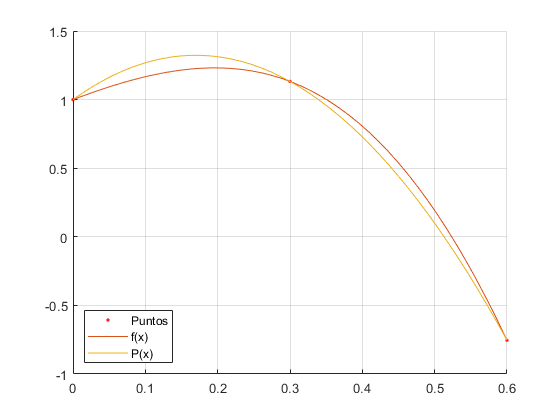

clear
syms f(x)

f(x) = exp(2 * x) * cos(3*x);

X = [0 .3 .6];
Y = eval(f(X));

C = newpoly(X, Y);
P = @(x) polyval(C, x);

clf('reset')
hold on
plot(X, Y, '.r')
fplot(f, [0, .6])
fplot(P, [0, .6])
legend('Puntos', 'f(x)', 'P(x)', 'Location', "southwest")
grid on
hold off


$$E\left(x\right)=\frac{f^{\left(n+1\right)} \left(x^* \right)}{\left(n+1\right)!}\;\prod_{i=0}^n \left(x-x_i \right)$$


J(x) = (x - 0)*(x - .3)*(x - .6)

$$J(x) = x\,\left(x-\frac{3}{5}\right)\,\left(x-\frac{3}{10}\right)$$

df = diff(f, 2 + 1); % n + 1 derivada
d2f = diff(df); % Derivada de f^(n+1)


$$\max \left\lbrace E\left(x\right)\right\rbrace =\frac{\max \left\lbrace {\;f}^{\left(n+1\right)} \left(x^* \right)\right\rbrace }{\left(n+1\right)!}\max \left\lbrace \prod_{i=0}^n \left(x-x_i \right)\right\rbrace \;$$


c = solve(d2f(x) == 0, x, "Real", true)

$$c = \left(\begin{array}{c} \frac{2\,\mathrm{atan}\left(\frac{7}{17}\right)}{3}\\ -\frac{2\,\mathrm{atan}\left(\frac{17}{7}\right)}{3} \end{array}\right)$$

c = eval(c(1))

c = 0.2604

eval(df(0)), eval(df(c)), eval(df(.6))

ans = -46

ans = -65.6522

ans = 5.5999

dJ(x) = diff(J);
j = eval(solve(dJ(x) == 0, x, "Real", true))

j =     0.1268
    0.4732


eval(J(0)), eval(J(j)), eval(J(.6))

ans = 0

ans =     0.0104
   -0.0104


ans = 0

E = eval( abs( f(c) / factorial(2 +1) * J(j(1)) ) )

E = 0.0021

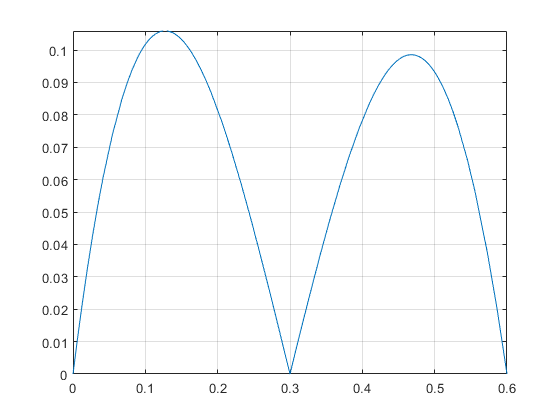

E = @(x) abs(f(x) - P(x));
fplot(E, [0, .6])
grid on

expand((x - 0)*(x - .3)*(x - .6))

$$ans = x^{3}-\frac{9\,x^{2}}{10}+\frac{9\,x}{50}$$

K = poly([0 .3 .6])

K =     1.0000   -0.9000    0.1800         0


poly2sym(K)

$$ans = x^{3}-\frac{9\,x^{2}}{10}+\frac{9\,x}{50}$$